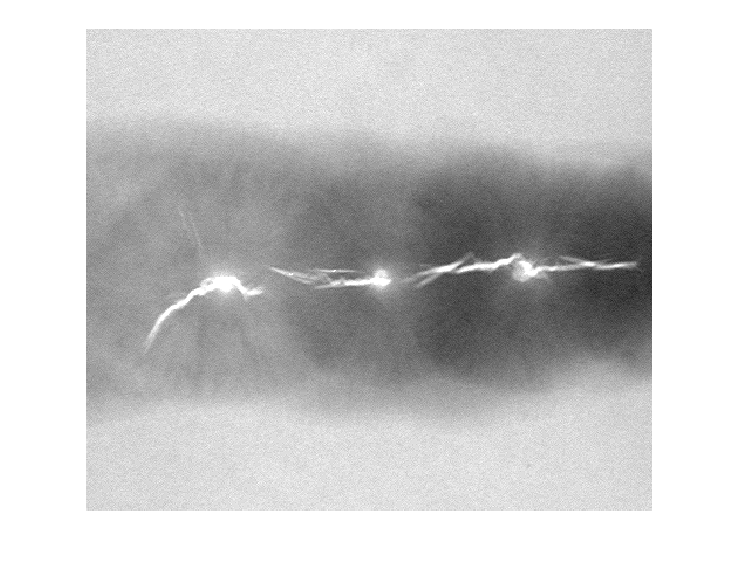

clc
clear

% I0 = imread('Fig1036(a)(original_septagon).tif');%导入图像
% 
% disp('Original image')
% imshow(I0)%显示该图像
% disp('Histogram of original image')
% figure, imhist(I0);%画出灰度图像的灰度直方图
% ylim([0 4e5]);
% 
% I1 = imread('Fig1036(b)(gaussian_noise_mean_0_std_10_added).tif');
% [~,e] = graythresh(I1)
% imshow(I1)
% figure, imhist(I1)
% ylim([0 14000]);
% 
% %人为给定阈值下，对上述图像进行分割
% T0 = 125 / 255;
% I1out = imbinarize(I1, T0);
% imshow(I1out)
% 
% I2 = imread('Fig1039(a)(polymersomes).tif');
% imshow(I2)
% figure, imhist(I2);
% % 
% %最大类间方差法分割上述图像(Otsu法)
% [T1, eta] = my_graythresh(I2);%取该图像的全局阈值
% T1 * 255
% eta
% I2out = imbinarize(I2, T1);%得出以上述阈值为基准的二值图像
% imshow(I2out)
% 
% I2 = imread('Fig1038(a)(noisy_fingerprint).tif');
% figure, imhist(I2)
% [T1, eta] = my_graythresh(I2);%取该图像的全局阈值
% T1 * 255
% eta
% I2out = imbinarize(I2, T1);%得出以上述阈值为基准的二值图像
% imshow(I2out)
% 
% I3 = imread('Fig1045(a)(iceberg).tif');
% imshow(I3)
% figure, imhist(I3);
% T2 = my_multithresh(I3, 2);
% I3out = label2rgb(imquantize(I3,T2));
% % 
% imshow(I3out)

I4 = imread('Fig1001(a)(constant_gray_region).tif');
I4 = imread('Fig1051(a)(defective_weld).tif');
imshow(I4)

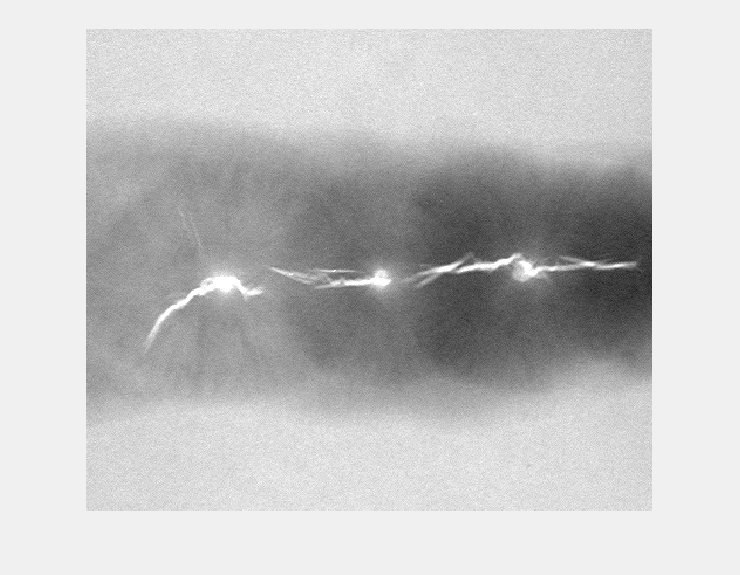

I4out = regiongrowseg(I4,0.18); 

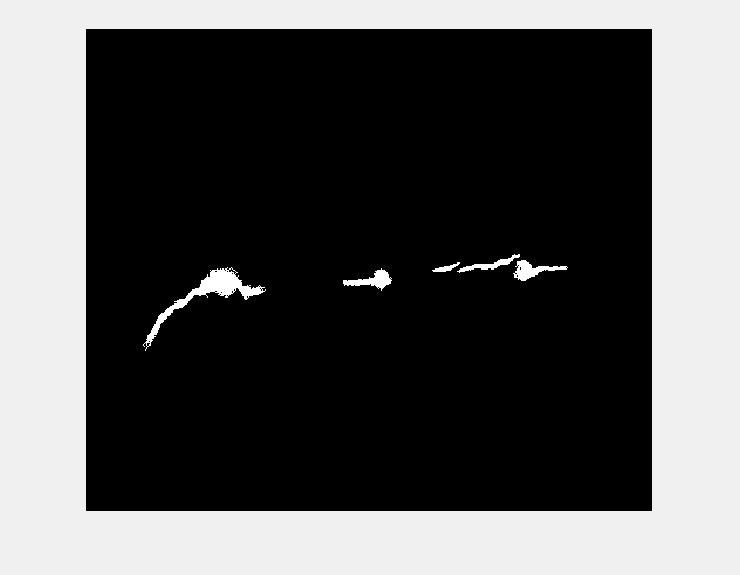

imshow(I4out)


% %给灰度图像增加噪声(均值0， 方差0.1)
% I0ns1 = imnoise(I0, 'gaussian', 0, 0.1);
% imshow(I0ns1)
% figure, imhist(I0ns1);
% ylim([0 1200])
% 
% %直接利用大津算法分割上述图像
% T2 = my_graythresh(I0ns1);
% I0b1 = imbinarize(I0ns1, T2);
% imshow(I0b1)